# Design Filter with Cutoff Frequencies

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code creates a watermarked signal. For more information, see the *Generating Signals and Common Signal Operations* module.

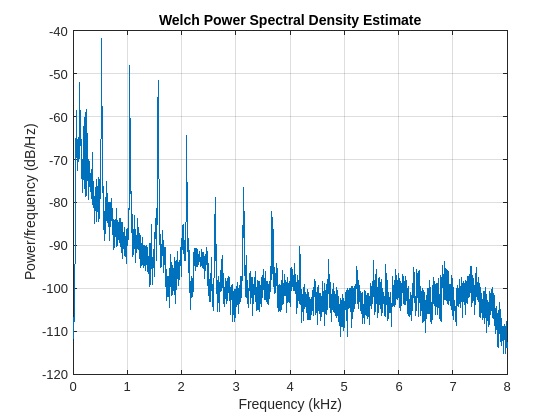

[flute,fs] = audioread("./data/NoisyFlute.wav");
flute = flute(1:3*fs);
t = ((0:numel(flute)-1)/fs)';
yin = chirp(t,2200,t(end),2500);
marked = flute + yin*0.0005;
pwelch(marked,[],[],[],fs)

## Tasks

Before you design the filter, you can change the frequency units from normalized to hertz by specifying the sample rate.

To start, you'll use the cutoff frequencies to design the filter. Bandpass and bandstop filters require two cutoff frequencies.

In the code at the top of the script, you can see that the chirp watermark extends from 2200 Hz to 2500 Hz. You can use those values as the cutoff frequencies for the bandpass filter.

In the code at the top of the script, you can see that the chirp watermark extends from 2200 Hz to 2500 Hz. You can use those values as the cutoff frequencies for the bandpass filter.

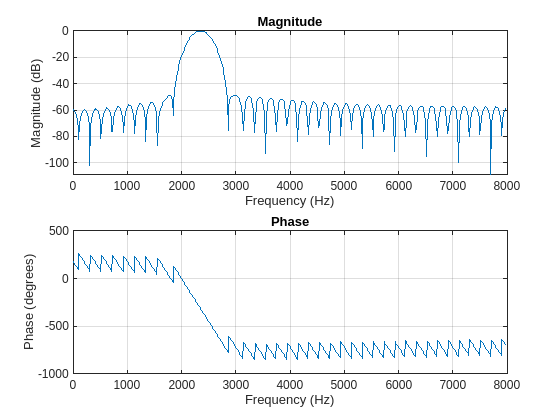

% Design a digital filter
designedFilter = designfilt('bandpassfir', ...
    'FilterOrder',80,'CutoffFrequency1',2200, ...
    'CutoffFrequency2',2500,'SampleRate',fs);

% Visualize magnitude and phase responses
freqz(designedFilter.Coefficients,1,[],fs)

Visualize the spectrum of the filtered signal

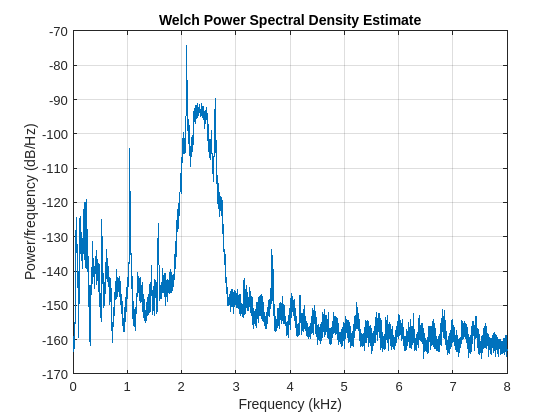

yout = filter(designedFilter,marked);
pwelch(yout,[],[],[],fs)